# Week 13

Exercise 1

clear
close all

Part a


sigma = linspace(-2000, 2000);
omega = linspace(-2000, 2000);

s = sigma + 1j*omega';


Part b

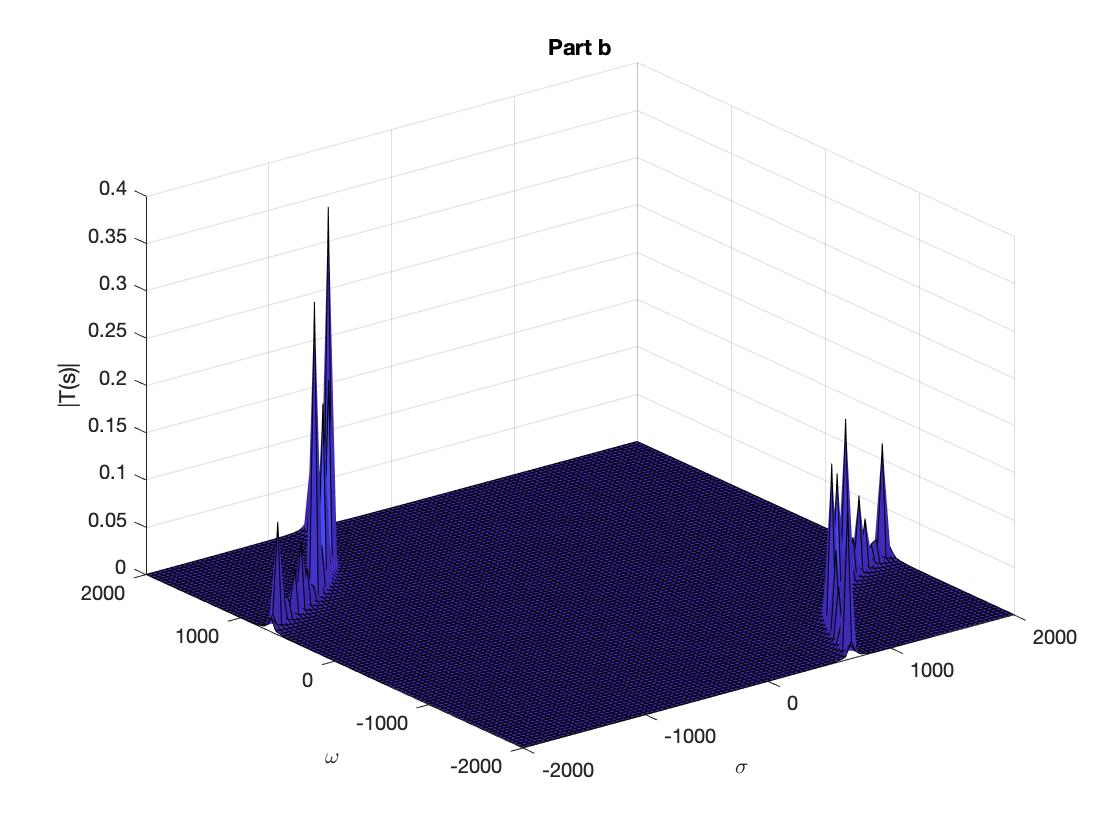


R = 100;
C = 10e-6;
L = 2.5;

T = @(s) 1./(L*C*s^2+R*C*s+1);
surf(sigma, omega, abs(T(s)));
title("Part b")
xlabel('\sigma')
ylabel('\omega')
zlabel('|T(s)|')

Part c

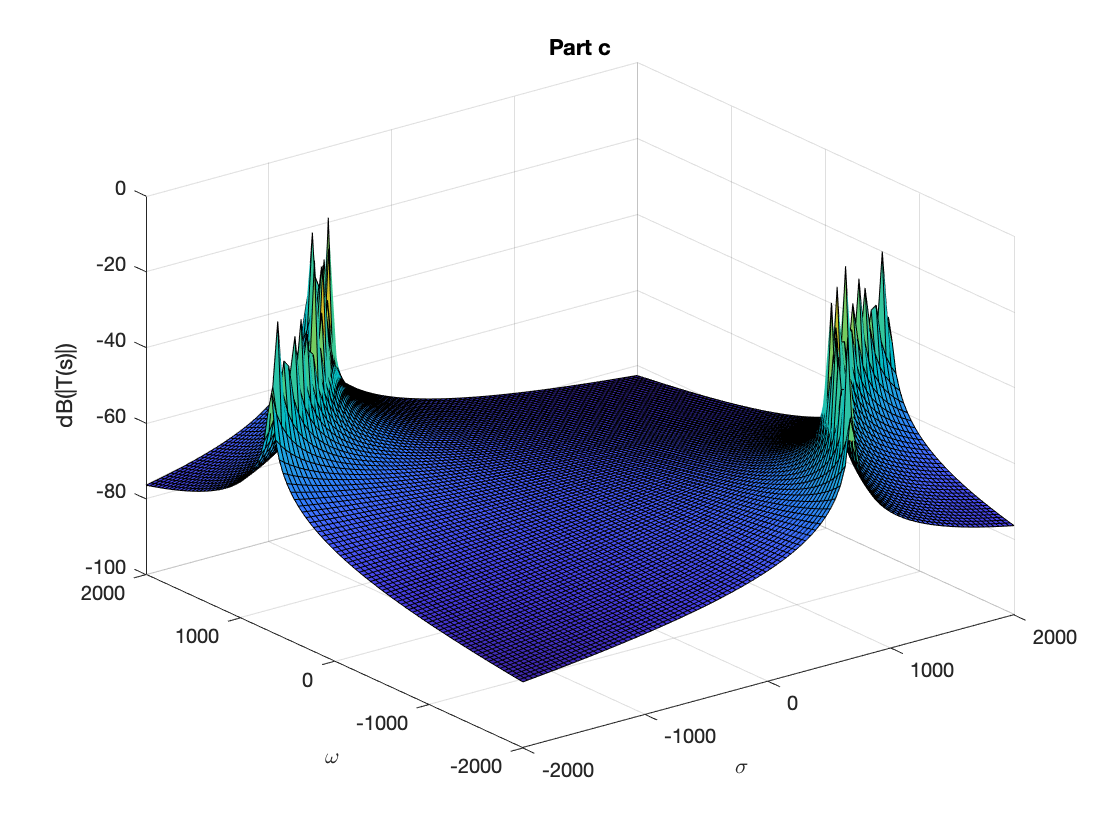


surf(sigma,omega,db(abs(T(s))))
title("Part c")
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

Part d

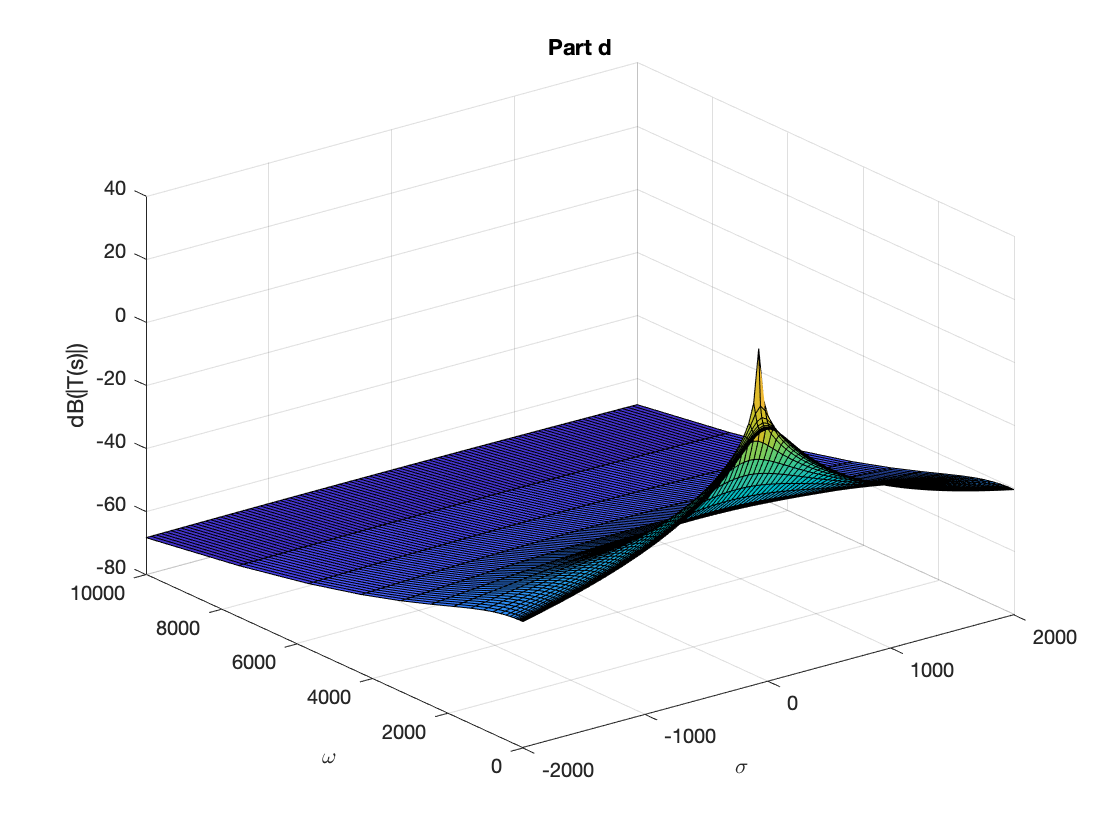


omega = logspace(-2, 4);
s = sigma + 1j*omega';
T = @(s) 1./(L*C*s.^2+R*C*s+1);

surf(sigma,omega,db(abs(T(s))))
title("Part d")
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

Part e


surf(sigma,omega,db(abs(T(s))))
set(gca, 'YScale', 'log');
title("Part e/f")
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')


Part f

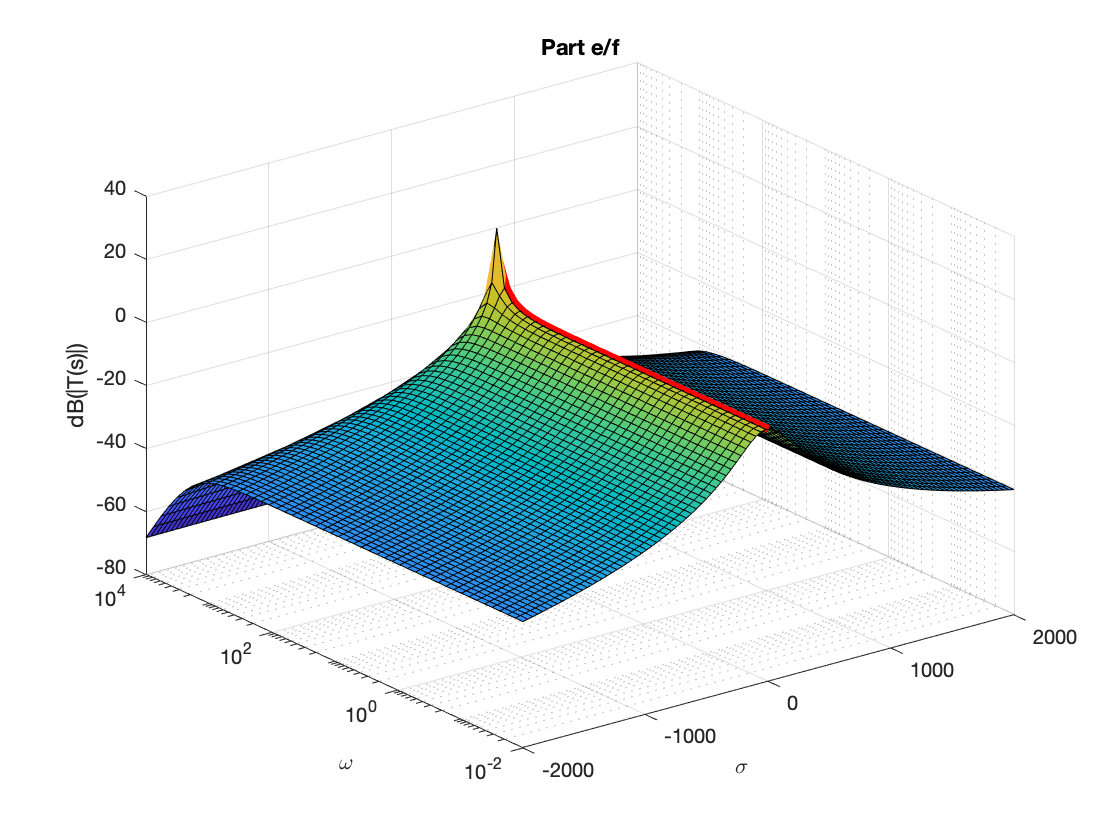

sigma = 0 * omega;
s = sigma + 1j*omega';
hold on
plot3(sigma,omega,db(abs(T(s))), 'r', 'LineWidth', 4)
hold off